Logica botones SET, PRUEBA, RESET y las colas como quiero que aparesca en ejecucion

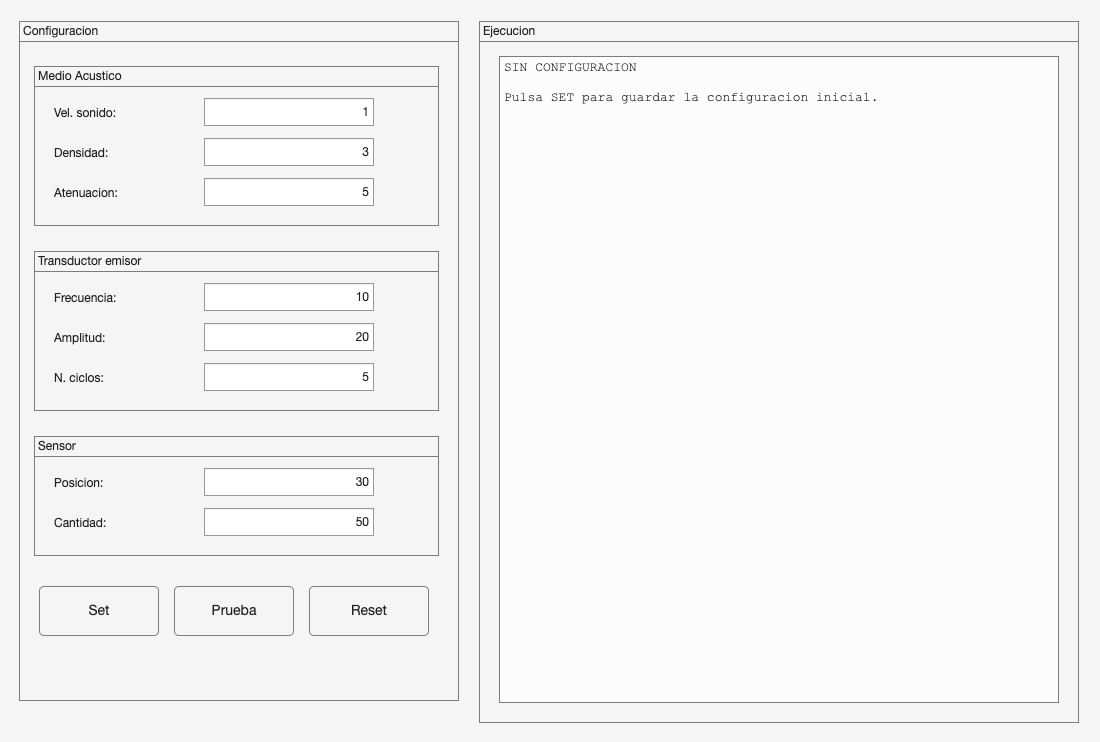

%% ============================================================
% QUS BENCHMARK
% TEST DE LOGICA:
%
% (i)   Una configuracion completa
% (ii)  Cola de una sola seccion
% (iii) Colas de varias secciones
%
% SET:
%   Primer SET  -> guarda configuracion completa (REF)
%   Siguientes  -> detectan cambios y construyen colas
%
% PRUEBA:
%   Solo muestra/imprime el estado actual.
%
% RESET:
%   Reinicia todo.
% ============================================================

clear;
clc;
close all;


%% ============================================================
% VENTANA
% ============================================================

fig = uifigure( ...
    'Name','QUS - Test logica experimental', ...
    'Position',[150 100 1100 720]);


%% ============================================================
% DATOS INTERNOS
% ============================================================

data.referenceDefined = false;

data.reference = struct();

data.queue = struct( ...
    'section',{}, ...
    'parameter',{}, ...
    'values',{}, ...
    'reference',{});

fig.UserData = data;


%% ============================================================
% PANEL CONFIGURACION
% ============================================================

left = uipanel(fig, ...
    'Title','Configuracion', ...
    'Position',[20 20 440 680]);


%% ============================================================
% MEDIO ACUSTICO
% ============================================================

p1 = uipanel(left, ...
    'Title','Medio Acustico', ...
    'Position',[15 475 405 160]);


uilabel(p1, ...
    'Text','Vel. sonido:', ...
    'Position',[20 100 120 25]);

soundSpeed = uieditfield(p1,'numeric', ...
    'Position',[170 100 170 28], ...
    'Value',1);


uilabel(p1, ...
    'Text','Densidad:', ...
    'Position',[20 60 120 25]);

density = uieditfield(p1,'numeric', ...
    'Position',[170 60 170 28], ...
    'Value',3);


uilabel(p1, ...
    'Text','Atenuacion:', ...
    'Position',[20 20 120 25]);

attenuation = uieditfield(p1,'numeric', ...
    'Position',[170 20 170 28], ...
    'Value',5);


%% ============================================================
% TRANSDUCTOR
% ============================================================

p2 = uipanel(left, ...
    'Title','Transductor emisor', ...
    'Position',[15 290 405 160]);


uilabel(p2, ...
    'Text','Frecuencia:', ...
    'Position',[20 100 120 25]);

frequency = uieditfield(p2,'numeric', ...
    'Position',[170 100 170 28], ...
    'Value',10);


uilabel(p2, ...
    'Text','Amplitud:', ...
    'Position',[20 60 120 25]);

amplitude = uieditfield(p2,'numeric', ...
    'Position',[170 60 170 28], ...
    'Value',20);


uilabel(p2, ...
    'Text','N. ciclos:', ...
    'Position',[20 20 120 25]);

cycles = uieditfield(p2,'numeric', ...
    'Position',[170 20 170 28], ...
    'Value',5);


%% ============================================================
% SENSOR
% ============================================================

p3 = uipanel(left, ...
    'Title','Sensor', ...
    'Position',[15 145 405 120]);


uilabel(p3, ...
    'Text','Posicion:', ...
    'Position',[20 60 120 25]);

sensorPosition = uieditfield(p3,'numeric', ...
    'Position',[170 60 170 28], ...
    'Value',30);


uilabel(p3, ...
    'Text','Cantidad:', ...
    'Position',[20 20 120 25]);

sensorNumber = uieditfield(p3,'numeric', ...
    'Position',[170 20 170 28], ...
    'Value',50);


%% ============================================================
% BOTONES
% ============================================================

setButton = uibutton(left,'push', ...
    'Text','Set', ...
    'FontSize',14, ...
    'Position',[20 65 120 50]);


testButton = uibutton(left,'push', ...
    'Text','Prueba', ...
    'FontSize',14, ...
    'Position',[155 65 120 50]);


resetButton = uibutton(left,'push', ...
    'Text','Reset', ...
    'FontSize',14, ...
    'Position',[290 65 120 50]);


%% ============================================================
% EJECUCION
% ============================================================

executionPanel = uipanel(fig, ...
    'Title','Ejecucion', ...
    'Position',[480 20 600 680]);


executionText = uitextarea(executionPanel, ...
    'Position',[20 20 560 625], ...
    'Editable','off', ...
    'FontName','Courier New', ...
    'FontSize',13);


executionText.Value = {
    'SIN CONFIGURACION'
    ''
    'Pulsa SET para guardar la configuracion inicial.'
    };


%% ============================================================
% GUARDAR HANDLES
% ============================================================

handles.soundSpeed = soundSpeed;
handles.density = density;
handles.attenuation = attenuation;

handles.frequency = frequency;
handles.amplitude = amplitude;
handles.cycles = cycles;

handles.sensorPosition = sensorPosition;
handles.sensorNumber = sensorNumber;

handles.executionText = executionText;

fig.UserData.handles = handles;


%% ============================================================
% CALLBACKS
% ============================================================

setButton.ButtonPushedFcn = ...
    @(src,event) onSet(fig);

testButton.ButtonPushedFcn = ...
    @(src,event) onTest(fig);

resetButton.ButtonPushedFcn = ...
    @(src,event) onReset(fig);




%% ============================================================
% FUNCIONES
% ============================================================


function config = readCurrentConfiguration(fig)

    h = fig.UserData.handles;


    % MEDIO ACUSTICO
    config.medium.sound_speed = h.soundSpeed.Value;
    config.medium.density = h.density.Value;
    config.medium.attenuation = h.attenuation.Value;


    % TRANSDUCTOR
    config.transducer.frequency = h.frequency.Value;
    config.transducer.amplitude = h.amplitude.Value;
    config.transducer.cycles = h.cycles.Value;


    % SENSOR
    config.sensor.position = h.sensorPosition.Value;
    config.sensor.number = h.sensorNumber.Value;

end



%% ============================================================
% SET
% ============================================================

function onSet(fig)

    data = fig.UserData;

    current = readCurrentConfiguration(fig);


    %% ========================================================
    % PRIMER SET
    %
    % CASO (i)
    %
    % Guarda TODA la configuracion.
    % NO existe cola todavia.
    % ========================================================

    if ~data.referenceDefined

        data.reference = current;
        data.referenceDefined = true;

        fig.UserData = data;


        fprintf('\n');
        fprintf('=============================================================\n');
        fprintf(' PRIMER SET - CONFIGURACION DE REFERENCIA GUARDADA\n');
        fprintf('=============================================================\n\n');


        updateExecutionPanel(fig);

        printPlan(fig);

        return;

    end


    %% ========================================================
    % SIGUIENTES SET
    %
    % Comparar configuracion actual contra REF.
    % ========================================================

    changes = detectChanges( ...
        data.reference, ...
        current);


    if isempty(changes)

        fprintf('\n[SET] No hay cambios respecto a REF.\n');

        updateExecutionPanel(fig);

        return;

    end


    %% ========================================================
    % AGREGAR CAMBIOS
    % ========================================================

    for i = 1:numel(changes)

        data.queue = addChange( ...
            data.queue, ...
            changes(i));

    end


    fig.UserData = data;


    %% ========================================================
    % MOSTRAR AUTOMATICAMENTE
    % ========================================================

    updateExecutionPanel(fig);

    printPlan(fig);

end



%% ============================================================
% PRUEBA
%
% NO modifica nada.
% Solo muestra el plan actual.
% ============================================================

function onTest(fig)

    updateExecutionPanel(fig);

    printPlan(fig);

end



%% ============================================================
% DETECTAR CAMBIOS
% ============================================================

function changes = detectChanges(ref,current)

    changes = struct( ...
        'section',{}, ...
        'parameter',{}, ...
        'value',{}, ...
        'reference',{});


    %% MEDIO ACUSTICO

    if current.medium.sound_speed ~= ref.medium.sound_speed

        changes(end+1) = makeChange( ...
            "Medio Acustico", ...
            "Vel. sonido", ...
            current.medium.sound_speed, ...
            ref.medium.sound_speed);
    end


    if current.medium.density ~= ref.medium.density

        changes(end+1) = makeChange( ...
            "Medio Acustico", ...
            "Densidad", ...
            current.medium.density, ...
            ref.medium.density);
    end


    if current.medium.attenuation ~= ref.medium.attenuation

        changes(end+1) = makeChange( ...
            "Medio Acustico", ...
            "Atenuacion", ...
            current.medium.attenuation, ...
            ref.medium.attenuation);
    end


    %% TRANSDUCTOR

    if current.transducer.frequency ~= ref.transducer.frequency

        changes(end+1) = makeChange( ...
            "Transductor emisor", ...
            "Frecuencia", ...
            current.transducer.frequency, ...
            ref.transducer.frequency);
    end


    if current.transducer.amplitude ~= ref.transducer.amplitude

        changes(end+1) = makeChange( ...
            "Transductor emisor", ...
            "Amplitud", ...
            current.transducer.amplitude, ...
            ref.transducer.amplitude);
    end


    if current.transducer.cycles ~= ref.transducer.cycles

        changes(end+1) = makeChange( ...
            "Transductor emisor", ...
            "N. ciclos", ...
            current.transducer.cycles, ...
            ref.transducer.cycles);
    end


    %% SENSOR

    if current.sensor.position ~= ref.sensor.position

        changes(end+1) = makeChange( ...
            "Sensor", ...
            "Posicion", ...
            current.sensor.position, ...
            ref.sensor.position);
    end


    if current.sensor.number ~= ref.sensor.number

        changes(end+1) = makeChange( ...
            "Sensor", ...
            "Cantidad", ...
            current.sensor.number, ...
            ref.sensor.number);
    end

end



function c = makeChange(section,parameter,value,reference)

    c.section = section;
    c.parameter = parameter;
    c.value = value;
    c.reference = reference;

end



%% ============================================================
% AGREGAR A COLA
% ============================================================

function queue = addChange(queue,change)

    index = [];


    for i = 1:numel(queue)

        sameSection = strcmp( ...
            queue(i).section, ...
            change.section);

        sameParameter = strcmp( ...
            queue(i).parameter, ...
            change.parameter);


        if sameSection && sameParameter

            index = i;

            break;

        end

    end


    %% Crear nueva entrada

    if isempty(index)

        entry.section = change.section;
        entry.parameter = change.parameter;
        entry.values = change.value;
        entry.reference = change.reference;

        queue(end+1) = entry;

        return;

    end


    %% Agregar valor si no existe

    values = queue(index).values;


    if ~any(values == change.value) && ...
       change.value ~= change.reference

        queue(index).values(end+1) = ...
            change.value;

    end

end



%% ============================================================
% ACTUALIZAR PANEL EJECUCION
% ============================================================

function updateExecutionPanel(fig)

    data = fig.UserData;
    h = data.handles;

    lines = strings(0);


    lines(end+1) = "PLAN DE EXPERIMENTOS";
    lines(end+1) = "================================================";


    %% ========================================================
    % SIN CONFIGURACION
    % ========================================================

    if ~data.referenceDefined

        lines(end+1) = "";
        lines(end+1) = "SIN CONFIGURACION";
        lines(end+1) = "";
        lines(end+1) = "Pulsa SET para guardar la configuracion inicial.";

        h.executionText.Value = cellstr(lines);

        return;

    end


    %% ========================================================
    % CASO (i)
    %
    % SOLO EXISTE LA CONFIGURACION INICIAL.
    %
    % MOSTRAR TODA LA CONFIGURACION.
    % ========================================================

    if isempty(data.queue)

        ref = data.reference;


        lines(end+1) = "";
        lines(end+1) = "TIPO: (i) CONFIGURACION UNICA";
        lines(end+1) = "";

        lines(end+1) = "SIMULACION 1";
        lines(end+1) = "------------------------------------------------";


        %% Medio

        lines(end+1) = "";
        lines(end+1) = "MEDIO ACUSTICO";

        lines(end+1) = ...
            "  Vel. sonido: " + ...
            num2str(ref.medium.sound_speed);

        lines(end+1) = ...
            "  Densidad: " + ...
            num2str(ref.medium.density);

        lines(end+1) = ...
            "  Atenuacion: " + ...
            num2str(ref.medium.attenuation);


        %% Transductor

        lines(end+1) = "";

        lines(end+1) = ...
            "TRANSDUCTOR EMISOR";

        lines(end+1) = ...
            "  Frecuencia: " + ...
            num2str(ref.transducer.frequency);

        lines(end+1) = ...
            "  Amplitud: " + ...
            num2str(ref.transducer.amplitude);

        lines(end+1) = ...
            "  N. ciclos: " + ...
            num2str(ref.transducer.cycles);


        %% Sensor

        lines(end+1) = "";

        lines(end+1) = ...
            "SENSOR";

        lines(end+1) = ...
            "  Posicion: " + ...
            num2str(ref.sensor.position);

        lines(end+1) = ...
            "  Cantidad: " + ...
            num2str(ref.sensor.number);


        lines(end+1) = "";
        lines(end+1) = "------------------------------------------------";
        lines(end+1) = "Configuraciones: 1";


        h.executionText.Value = cellstr(lines);

        return;

    end


    %% ========================================================
    % YA EXISTE UNA COLA
    % ========================================================

    sections = string({data.queue.section});

    uniqueSections = unique( ...
        sections, ...
        'stable');

    numberSections = numel(uniqueSections);


    %% ========================================================
    % CASO (ii)
    % ========================================================

    if numberSections == 1

        lines(end+1) = "";
        lines(end+1) = ...
            "TIPO: (ii) UNA SECCION VARIABLE";


    %% ========================================================
    % CASO (iii)
    % ========================================================

    else

        lines(end+1) = "";
        lines(end+1) = ...
            "TIPO: (iii) VARIAS SECCIONES VARIABLES";

    end


    %% ========================================================
    % MOSTRAR COLAS
    % ========================================================

    for s = 1:numberSections

        sectionName = uniqueSections(s);


        lines(end+1) = "";

        lines(end+1) = ...
            "SIMULACION " + s;

        lines(end+1) = ...
            "------------------------------------------------";

        lines(end+1) = ...
            upper(sectionName);


        for q = 1:numel(data.queue)

            if strcmp( ...
                    data.queue(q).section, ...
                    sectionName)


                valuesString = ...
                    formatValues( ...
                        data.queue(q).values);


                lines(end+1) = ...
                    "  " + ...
                    data.queue(q).parameter + ...
                    ": [" + ...
                    valuesString + ...
                    ", REF=" + ...
                    num2str(data.queue(q).reference) + ...
                    "]";

            end

        end

    end


    lines(end+1) = "";
    lines(end+1) = "================================================";

    lines(end+1) = ...
        "Secciones variables: " + numberSections;


    h.executionText.Value = ...
        cellstr(lines);

end



%% ============================================================
% IMPRIMIR EN COMMAND WINDOW
% ============================================================

function printPlan(fig)

    data = fig.UserData;


    fprintf('\n');
    fprintf('=============================================================\n');
    fprintf('                  PLAN DE EXPERIMENTOS\n');
    fprintf('=============================================================\n');


    if ~data.referenceDefined

        fprintf('\nSIN CONFIGURACION.\n');

        return;

    end


    %% ========================================================
    % CASO I
    % ========================================================

    if isempty(data.queue)

        ref = data.reference;


        fprintf('\n');
        fprintf('TIPO: (i) CONFIGURACION UNICA\n\n');

        fprintf('SIMULACION 1\n');
        fprintf('-------------------------------------------------------------\n');


        fprintf('\nMEDIO ACUSTICO\n');

        fprintf('  Vel. sonido: %g\n', ...
            ref.medium.sound_speed);

        fprintf('  Densidad: %g\n', ...
            ref.medium.density);

        fprintf('  Atenuacion: %g\n', ...
            ref.medium.attenuation);


        fprintf('\nTRANSDUCTOR EMISOR\n');

        fprintf('  Frecuencia: %g\n', ...
            ref.transducer.frequency);

        fprintf('  Amplitud: %g\n', ...
            ref.transducer.amplitude);

        fprintf('  N. ciclos: %g\n', ...
            ref.transducer.cycles);


        fprintf('\nSENSOR\n');

        fprintf('  Posicion: %g\n', ...
            ref.sensor.position);

        fprintf('  Cantidad: %g\n', ...
            ref.sensor.number);


        fprintf('\n');
        fprintf('CONFIGURACIONES: 1\n');

        fprintf('=============================================================\n');

        return;

    end


    %% ========================================================
    % CASO II / III
    % ========================================================

    sections = string({data.queue.section});

    uniqueSections = unique( ...
        sections, ...
        'stable');

    numberSections = numel(uniqueSections);


    fprintf('\n');


    if numberSections == 1

        fprintf('TIPO: (ii) UNA SECCION VARIABLE\n');

    else

        fprintf('TIPO: (iii) VARIAS SECCIONES VARIABLES\n');

    end


    fprintf('\n');


    for s = 1:numberSections

        sectionName = uniqueSections(s);


        fprintf('-------------------------------------------------------------\n');

        fprintf('SIMULACION %d\n',s);

        fprintf('-------------------------------------------------------------\n');

        fprintf('%s\n\n',upper(sectionName));


        for q = 1:numel(data.queue)

            if strcmp( ...
                    data.queue(q).section, ...
                    sectionName)


                fprintf('  %s: [', ...
                    data.queue(q).parameter);


                values = data.queue(q).values;


                for v = 1:numel(values)

                    fprintf('%g',values(v));


                    if v < numel(values)

                        fprintf(', ');

                    end

                end


                fprintf(', REF=%g]\n', ...
                    data.queue(q).reference);

            end

        end


        fprintf('\n');

    end


    fprintf('=============================================================\n');

    fprintf('SECCIONES VARIABLES: %d\n', ...
        numberSections);

    fprintf('=============================================================\n');

end



%% ============================================================
% FORMAT VALUES
% ============================================================

function txt = formatValues(values)

    pieces = strings(1,numel(values));


    for i = 1:numel(values)

        pieces(i) = ...
            num2str(values(i));

    end


    txt = strjoin(pieces,", ");

end



%% ============================================================
% RESET
% ============================================================

function onReset(fig)

    data = fig.UserData;


    data.referenceDefined = false;

    data.reference = struct();


    data.queue = struct( ...
        'section',{}, ...
        'parameter',{}, ...
        'values',{}, ...
        'reference',{});


    fig.UserData = data;


    updateExecutionPanel(fig);


    fprintf('\n');
    fprintf('============================\n');
    fprintf('RESET COMPLETO\n');
    fprintf('============================\n\n');

end